clc;clear;

load('TestSdo.mat')
load('DatosExperimentales.mat')
ePRBS=TexpPRBS-TestPRBS;
eSTEP=TexpSTEP-TestSTEP;
mean(ePRBS)

ans = -0.0035

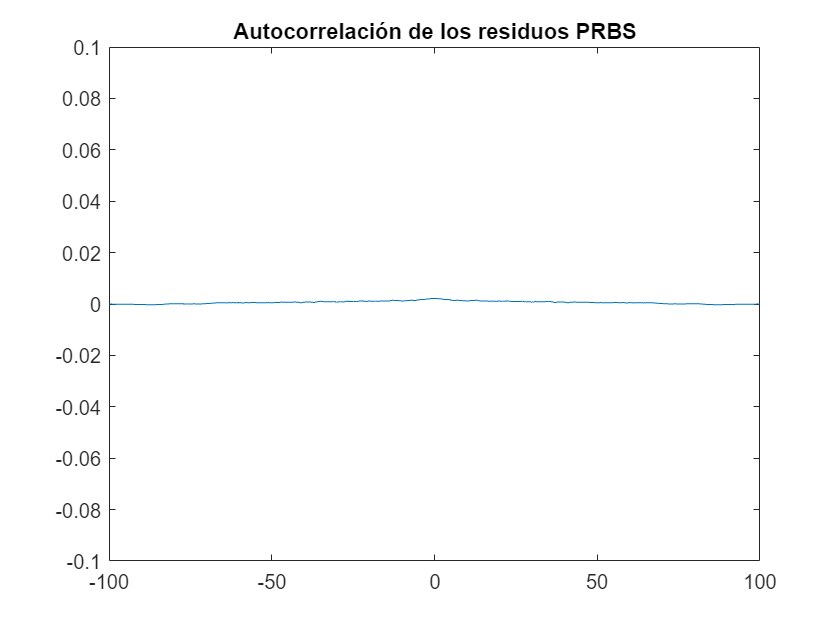

[c, lags] = xcorr(ePRBS);
lags(101)=[];
c(101)=[];
plot(lags,c)
title("Autocorrelación de los residuos PRBS")
ylim(0.1*[-1,1])

mean(eSTEP)

ans = 5.3714e-04

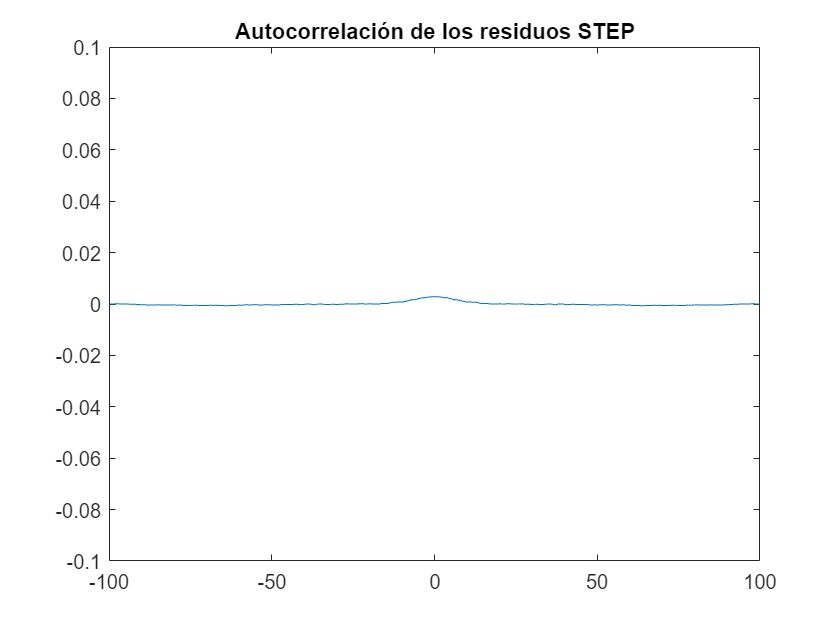

[c, lags] = xcorr(eSTEP);
lags(101)=[];
c(101)=[];
plot(lags,c)
title("Autocorrelación de los residuos STEP")
ylim(0.1*[-1,1])

%Parametros estimados con los datos experimentales con la interfaz grafica
Par0=[0.19439 0.8847 0.20195 0.28279 0.12976 0.90663 0.89657 0.59684 0.90992 0.31548 0.8372 1.3221 1.0005 0.052278 0.27736]';

% Repeticion de la estimacion
N=100;
Npar=15;
eN=length(ePRBS);
Par=zeros(Npar,N);
for i=1:N
    ePRBSs=datasample(ePRBS,eN); %remuestreos con remplazo
    eSTEPs=datasample(eSTEP,eN);
    TPRBSnew=TestPRBS+ePRBSs;
    TSTEPnew=TestSTEP+eSTEPs;
    if strcmp(get_param('modelo_sdo','Dirty'),'on')
      save_system;
    end
    [pOpt,~] = EstimacionSdo([],TPRBSnew,TSTEPnew);
    Par(:,i)=[pOpt(:).Value]';
end

Configuring parallel workers for optimization...
Analyzing and transferring files to the workers ...done.
Analyzing and transferring files to the workers ...done.
Parallel workers configured for optimization.

 Optimization started 2023-Oct-20, 18:36:31

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     31     0.151215            1                                         
    1     62     0.151215      0.06554         22.2
    2     93     0.145306      0.01639         31.2
    3    124      0.14203      0.01639         44.9
    4    155     0.138455     0.004096         37.3
    5    186     0.136348     0.001024           26
    6    217     0.135956     0.001024         19.3
    7    248     0.135956     0.000256         19.3
    8    279     0.135956      6.4e-05         19.3
Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping 

% %Calcular los intervalos de confianza
conf=0.95;
int_conf = zeros(Npar,2);
for i=1:Npar
    x=Par(i,:);
    N = length(x);
    xbar = mean(x);
    sigma = std(x);
    alpha = 1 - conf;
    linf = alpha/2; lsup = 1 - alpha/2;
    nu = N - 1; % Grados de libertad de la distribución t de Student
    t_stud = tinv([linf lsup], nu);
    int_conf(i,:) = xbar + t_stud*sigma/sqrt(N);
end
error_abs = round(abs(int_conf(:,2) - Par0),2,'significant');
error_rel = round(abs((error_abs./Par0))*100,2,'significant');
parNames={'alpha','c3','a1','a2','a3','b1','c1','c2','c4','d1','d2','r1','r2','rho','s'};
tab=array2table([Par0 error_abs error_rel], 'RowNames',parNames,'VariableNames',{'Estimados', 'Intervalo de confianza', 'Error relativo(%)'});
disp(tab)

             Estimados    Intervalo de confianza    Error relativo(%)
             _________    ______________________    _________________

    alpha     0.19439             0.0014                   0.72      
    c3         0.8847             0.0081                   0.92      
    a1        0.20195              0.036                     18      
    a2        0.28279               0.13                     46      
    a3        0.12976               0.12                     92      
    b1        0.90663              5e-05                 0.0055      
    c1        0.89657              0.015                    1.7      
    c2        0.59684              0.023                    3.9      
    c4        0.90992             0.0068    